load("E:\Result\24-7-14iEMG-sEMG\数据处理\MUAPCCL1T2-3.mat")
muap=MUAPCCL1T2{1,1};
figure;
plotArrayPotential(muap,1,1);


%对muap进行pca降噪,电极片为13*5
%Lundsberg, J., Björkman, A., Malesevic, N. et al. 
%Inferring position of motor units from high-density surface EMG. Sci Rep 14, 3858 (2024). 
% https://doi.org/10.1038/s41598-024-54405-1
muap_recon=muap_pca(muap,0.95);

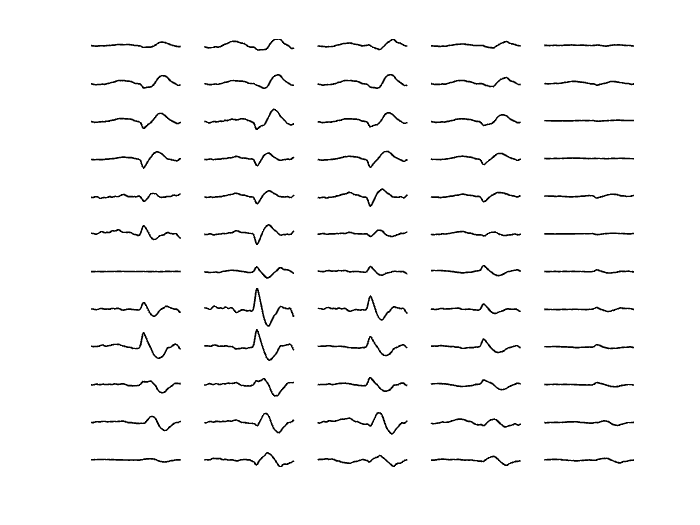

%上下差分的MUAP图
% tmpmuap=muap_cog;
% % tmpmuap{1,1}=tmpmuap{2,1};
% for i=1:12
%     for j=1:5
%         % tmpmuap{1,1}=zeros(1,50);
%         difmuap{i,j}=tmpmuap{i+1,j}-tmpmuap{i,j};
%     end
% end
% figure;
% plotArrayPotential(difmuap,1,1);

%%使用curve fit toolbox拟合高斯曲面
%拟合曲线
ftt=fittype("A*exp(-(a*(x-x0)^2+2*b*(x-x0)*(y-y0)+c*(y-y0)^2))", ...
    'independent', {'x','y'}, 'dependent', {'h'}, ...
        'coefficients',{'A','x0','y0','a','b','c'});
% ftt=fittype("A*exp(-(cos(theta)^2/(2*sigma_x^2)+sin(theta)^2/(2*sigma_y^2)*(x-x0)^2+" + ...
%     "2*sin(2*theta)/(4*sigma_x^2)+sin(2*theta)^2/(4*sigma_y^2)*(x-x0)*(y-y0)+" + ...
%     "sin(theta)^2/(2*sigma_x^2)+cos(theta)^2/(2*sigma_y^2)*(y-y0)^2))", ...
%     'independent', {'x','y'}, 'dependent', {'h'}, ...
%         'coefficients',{'A','x0','y0','sigma_x','sigma_y','theta'});

%计算
h=p2p_norm;
h=reshape(h,[],1);
x_mat=reshape(x,[],1);
y_mat=reshape(y,[],1);
[sf,gof,output]=fit([x_mat,y_mat],h,ftt,'StartPoint',[1,2,5,1,1,1])

sf =      常规模型:
     sf(x,y) = A*exp(-(a*(x-x0)^2+2*b*(x-x0)*(y-y0)+c*(y-y0)^2))
     系数(置信边界为 95%):
       A =      0.7772  (0.6806, 0.8738)
       x0 =       3.731  (3.482, 3.981)
       y0 =       4.599  (4.043, 5.155)
       a =      0.1127  (0.08262, 0.1427)
       b =   -0.003392  (-0.01742, 0.01063)
       c =     0.03601  (0.0167, 0.05532)

gof = 包含以下字段的 struct :
           sse: 1.1459
       rsquare: 0.6862
           dfe: 58
    adjrsquare: 0.6591
          rmse: 0.1406


output = 包含以下字段的 struct :
             numobs: 64
           numparam: 6
          residuals: [64×1 double]
           Jacobian: [64×6 double]
           exitflag: 3
      firstorderopt: 7.3034e-04
         iterations: 22
          funcCount: 161
       cgiterations: 0
          algorithm: 'trust-region-reflective'
           stepsize: 5.2526e-04
            message: '成功，但拟合停止，因为残差的变化小于容差(TolFun)。'
       bestfeasible: []
    constrviolation: []


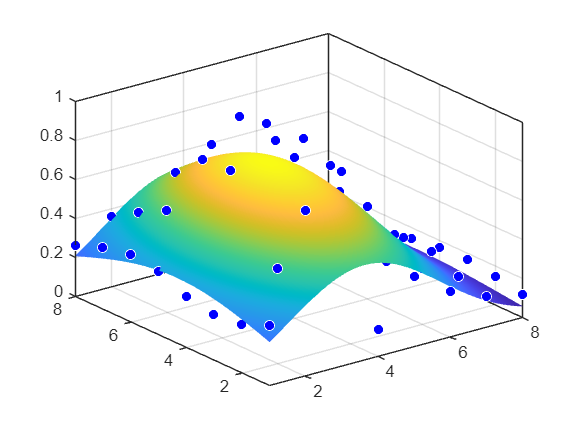

%绘图
clf
plot(sf,[x_mat,y_mat],h)
hold on
shading interp
colormap('parula')

% 使用算法


%%通过abc计算sigma和转角theta
a=sf.a;b=sf.b;c=sf.c;
F=@(x)[-a+cos(x(1))^2/(2*x(2)^2)+sin(x(1))^2/(2*x(3)^2);
    -b-sin(2*x(1))/(4*x(2)^2)+sin(2*x(1))^2/(4*x(3)^2);
    -c+sin(x(1))^2/(2*x(2)^2)+cos(x(1))^2/(2*x(3)^2);];
x0=[0;2;2];%第一位旋转角
% options = optimoptions('fsolve','Display','iter');
[x,fval] = fsolve(F,x0);


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


GAUSSIAN_coef.theta=x(1);
GAUSSIAN_coef.sigma_x=x(2);
GAUSSIAN_coef.sigma_y=x(3);
GAUSSIAN_coef.A=sf.A;GAUSSIAN_coef.x0=sf.x0;GAUSSIAN_coef.y0=sf.y0;

%%使用单层容积导体模型
Q=1;%衰减强度?
r=40;
r=r/cos(GAUSSIAN_coef.theta)^2

r = 40.0377

FWHM=2*sqrt(2*log(2))*GAUSSIAN_coef.sigma_y%sigamx还是y？ sigma_x:平行肌纤维 sigma_y:垂直

FWHM = 8.7801

alpha=FWHM/(2*r)

alpha = 0.1096


d=(2*r^2*cos(alpha)-2*r^2+(log(2)/Q)^2)/(2*(r*cos(alpha)-r-log(2)/Q))

d = 10.0542